# Forecast ARIMA Model

Forecast NASDAQ daily closing prices over a 500-day horizon. 

Load the US equity indices data set.

load Data_EquityIdx

The data set contains daily NASDAQ closing prices from 1990 through 2001. For more details, enter `Description` at the command line.

Assume that an ARIMA(1,1,1) model is appropriate for describing the first 1500 NASDAQ closing prices. Create an ARIMA(1,1,1) model template.

Mdl = arima(1,1,1);

`estimate` requires a presample of size `Mdl.P` = 2.

Fit the model to the data.  Specify the first two observations as a presample.

idxpre = 1:Mdl.P;
idxest = (Mdl.P + 1):1500;
EstMdl = estimate(Mdl,DataTable.NASDAQ(idxest),...
    'Y0',DataTable.NASDAQ(idxpre));

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.43291       0.18607          2.3266       0.019989
    AR{1}       -0.076323      0.082045        -0.93026        0.35223
    MA{1}         0.31312      0.077284          4.0516     5.0876e-05
    Variance        27.86       0.63785          43.678              0



Forecast the closing values into a 500-day horizon by passing the estimated model to `forecast`. To initialize the model for forecasting, specify the last two observations in the estimation data as a presample.

yf0 = DataTable.NASDAQ(idxest(end - 1:end));
yf = forecast(EstMdl,500,yf0);

Plot the first 2000 observations and the forecasts. 

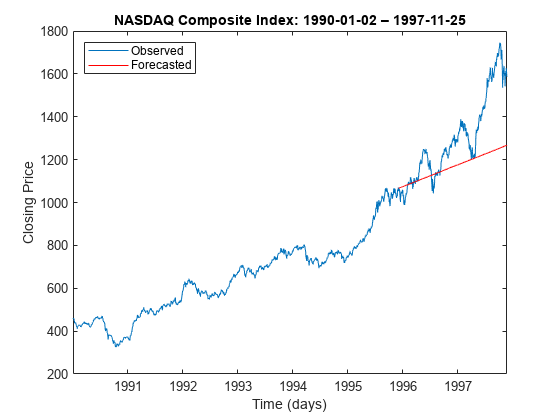

dates = datetime(dates,'ConvertFrom',"datenum",...
    'Format',"yyyy-MM-dd");

figure
h1 = plot(dates(1:2000),DataTable.NASDAQ(1:2000));
hold on
h2 = plot(dates(1501:2000),yf,'r');
legend([h1 h2],"Observed","Forecasted",...
	     'Location',"NorthWest")
title("NASDAQ Composite Index: 1990-01-02 – 1997-11-25")
xlabel("Time (days)")
ylabel("Closing Price")
hold off

After the start of 1995, the model forecasts almost always underestimate the true closing prices.

*Copyright 2019 The MathWorks, Inc.*